addpath(genpath('./pandemic_model'));
addpath(genpath('./yaml'));
arrival_dist = load_arrival_dist("./pandemic-loss-modeling/output/arrival_distributions/all_risk_default.yaml");
duration_dist = load_duration_dist("./pandemic-loss-modeling/output/duration_distributions/all_risk_default.yaml");

num_simulations = 10000;
sim_periods = 200;
severity_matrix = arrival_dist.get_severity(unifrnd(0, 1, num_simulations, sim_periods));
duration_matrix = duration_dist.get_duration(unifrnd(0, 1, num_simulations, sim_periods));

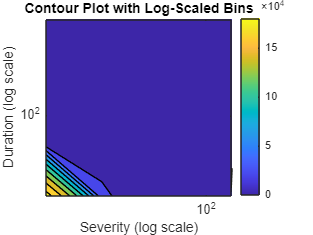

sev_censored = severity_matrix(severity_matrix > arrival_dist.min_severity);
duration_censored = duration_matrix(severity_matrix > arrival_dist.min_severity);
bin_edges_severity = logspace(log10(min(sev_censored)), log10(max(sev_censored)), 10);
bin_edges_duration = logspace(log10(min(duration_censored)), log10(max(duration_censored)), 10);

% Compute the histogram with custom bins
[N, c] = hist3([sev_censored, duration_censored], [20 20]);

% Create the contour plot
contourf(c{1}, c{2}, N');
colorbar; % Optional: adds a color bar for reference
set(gca, 'YScale', 'log');
set(gca, 'XScale', 'log');
xlabel('Severity (log scale)');
ylabel('Duration (log scale)');
title('Contour Plot with Log-Scaled Bins');

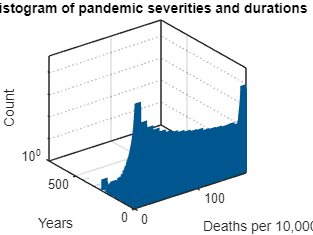

histogram2(sev_censored, duration_censored);
xlabel("Deaths per 10,000");
ylabel("Years");
zlabel("Count");
title("Histogram of pandemic severities and durations")
set(gca, 'ZScale', 'log');

duration_dist.pd.icdf(0.95)

ans = 25.0395